# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.6 特殊绘图

#### 2.6.20 跳动的心

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

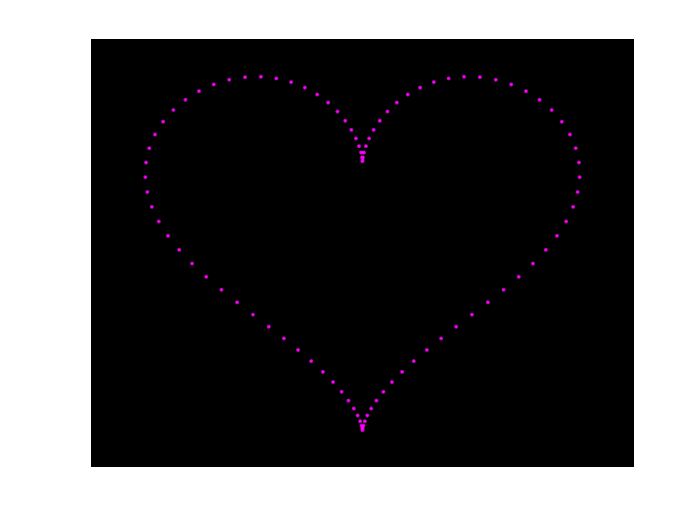

clear; clc;
n = 100;
t = linspace(0, 2*pi, n);
% 心形图极坐标表示法
x = 16*sin(t).^3;
y = 13*cos(t) - 5*cos(2*t) - 2*cos(3*t) - cos(4*t);
handle = scatter(x, y, '.m');
% 调整背景和范围
ax = gca;
ax.Color = [0, 0, 0];
ax.XColor = 'none';
ax.YColor = 'none';
hold on;
handle0 = scatter(x, y, '.m');
hold off;

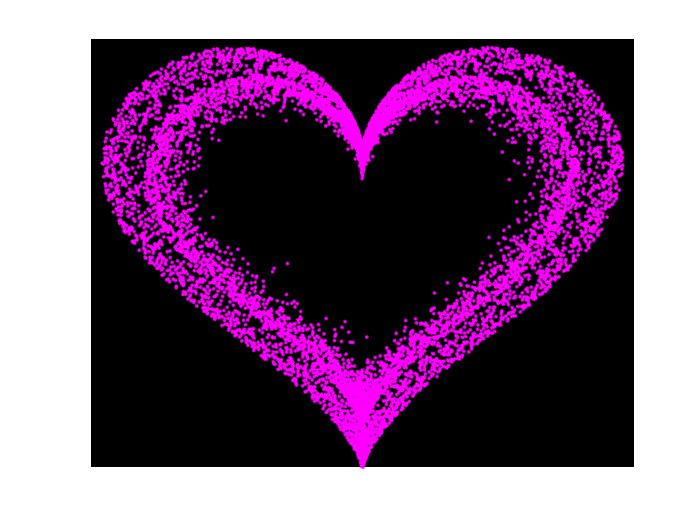

% 随机分布的爱心效果
n = 5000;
t = linspace(0, 2*pi, n);
% 径向随机缩放
r = 10 - abs(normrnd(10, 1, [1, n]) - 10);
x = 16*sin(t).^3;
y = 13*cos(t) - 5*cos(2*t) - 2*cos(3*t) - cos(4*t);
x = r.*x;
y = r.*y;
ax.XLim = [-200, 200];
ax.YLim = [-200, 150];
handle.XData = x;
handle.YData = y;
handle0.XData = 1.2*x;
handle0.YData = 1.2*y;

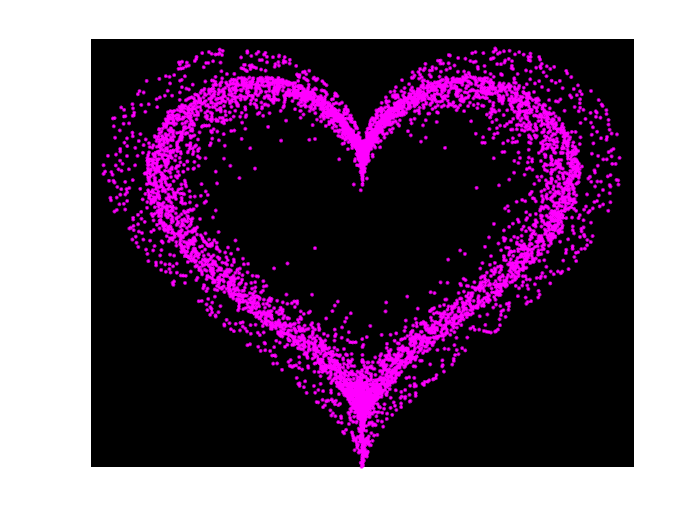

% 径向有规律缩放
len = 2000;
tt = linspace(0, 2*pi, len);
for i = 1:len
    % 背景随机一组大点的心形
    r0 = 10 - abs(normrnd(10, 2, [1, len]) - 10);
    x0 = r0 * 16.*sin(tt).^3;
    y0 = r0 .* (13*cos(tt) - 5*cos(2*tt) - 2*cos(3*tt) - cos(4*tt));
    handle0.XData = 1.2*x0;
    handle0.YData = 1.2*y0;
    
    % 根据距离缩放
    d = sqrt(x.^2 + y.^2);
    l = (d - min(d)) / (max(d) - min(d));
    c = 1 + (2 - 1.8*l)/8.*sin(80*tt(i));
    handle.XData = c.*x;
    handle.YData = c.*y;    
    drawnow;
    pause(0.01);
end